Leo los datos extraídos de la respuesta al esclón

% addpath('./../../mediciones/');

step_resp_ris = open('escalon_subida.CSV')

step_resp_ris = struct with fields:
        data: [30000×4 double]
    textdata: {10×6 cell}


step_t = step_resp_ris.data(:,2);
step_y = step_resp_ris.data(:,3);
step_u = step_resp_ris.data(:,4);
ts_esc = 0.0001000000000;

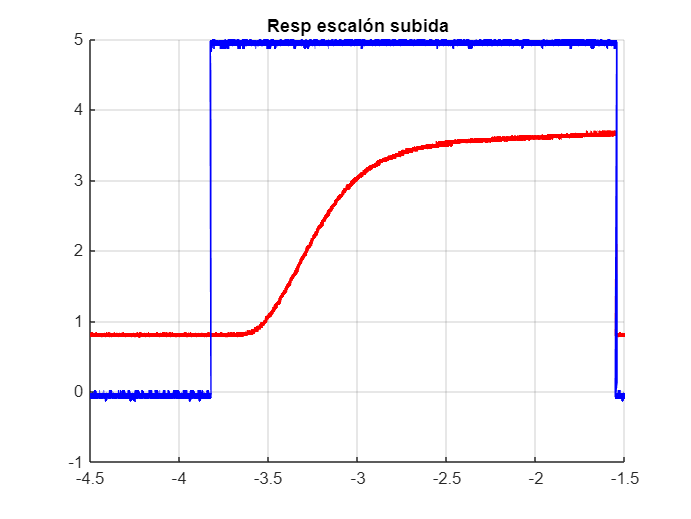

figure();
grid on; hold on;
title('Resp escalón subida');

plot(step_t, step_y, 'r', 'LineWidth', 2);
plot(step_t, step_u, 'b', 'LineWidth', 2);

Proceso la información para quedarme solo con el escalón de subida

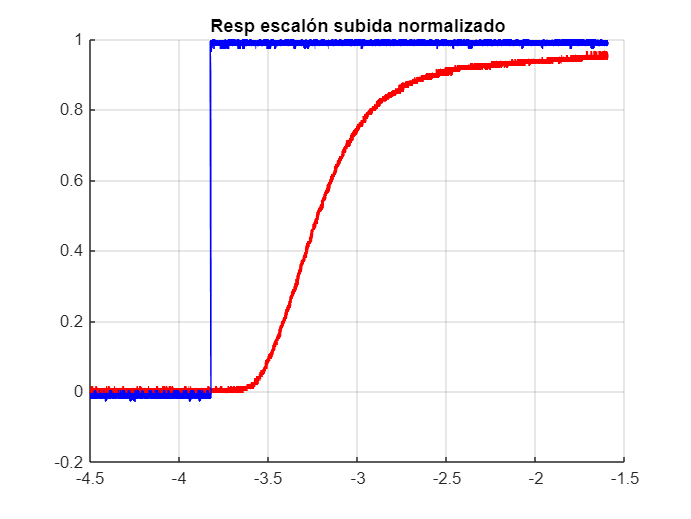

esc_y = step_y(1:(end-1e3))-1;
esc_u = step_u(1:(end-1e3));
esc_t = step_t(1:(end-1e3));

esc_y_norm=(esc_y-esc_y(1))/3;
esc_u_norm=esc_u/5;

figure();
grid on; hold on;
title('Resp escalón subida normalizado');

plot(esc_t, esc_y_norm, 'r', 'LineWidth', 2);
plot(esc_t, esc_u_norm, 'b', 'LineWidth', 2);

Proceso la información para quedarme solo con el escalón de bajada

step_resp_fal = open('escalon_bajada.CSV')

step_resp_fal = struct with fields:
        data: [30000×4 double]
    textdata: {10×6 cell}


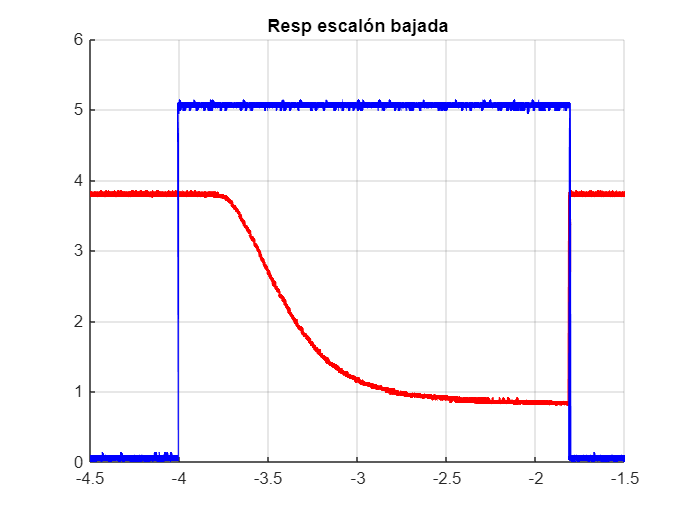

step_t_fal = step_resp_fal.data(:,2);
step_y_fal = step_resp_fal.data(:,3);
step_u_fal = step_resp_fal.data(:,4)*-1+5;
ts_esc_fal = 0.0001000000000;

figure();
grid on; hold on;
title('Resp escalón bajada');

plot(step_t_fal, step_y_fal, 'r', 'LineWidth', 2);
plot(step_t_fal, step_u_fal, 'b', 'LineWidth', 2);

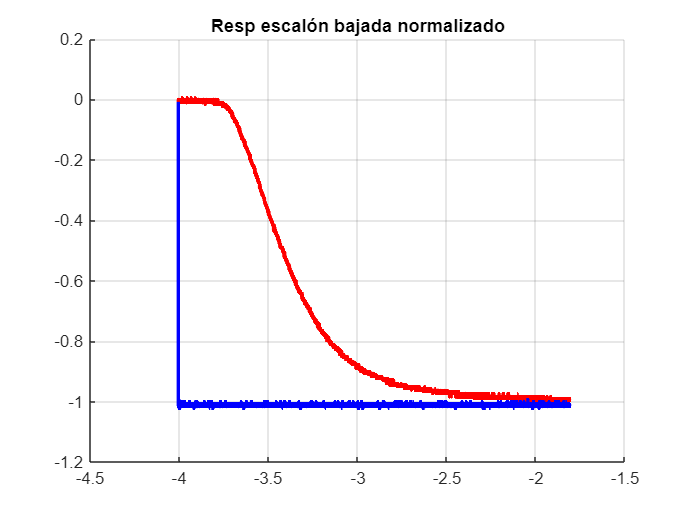

starting_index = find(step_u_fal > 0.5, 1)-1;
end_index = find(step_u_fal > 0.5, 1, "last");

esc_y_fal = step_y_fal(starting_index:end_index);
esc_u_fal = step_u_fal(starting_index:end_index);
esc_t_fal = step_t_fal(starting_index:end_index);

esc_y_fal_norm=(esc_y_fal-esc_y_fal(1))/3;
esc_u_fal_norm=esc_u_fal/-5;

figure();
grid on; hold on;
title('Resp escalón bajada normalizado');

plot(esc_t_fal, esc_y_fal_norm, 'r', 'LineWidth', 2);
plot(esc_t_fal, esc_u_fal_norm, 'b', 'LineWidth', 2);